# Task Data Inversion

The initial idea was to extract intrinsic connectivity from resting state data and then used these connectivity estimates when modeling task data.

So far we haven't had much success in capturing true directed connectivity parameters using sparse rDCM. 

But resting state data isn't the only place we can recover connectivity estimates from. In fact, the model with pruning is more extensively tested for task data. 

So in this notebook 

- we generate data with input (i.e. task data), 

- invert the model with pruning

- inspect connectivity and task parameter estimates

- generate data for a second task

- show how task involvement is overestimated without accounting for connectivity

- use recovered connectivity parameters from the first task to estimate the task parameters in the second task

cmap = mycmap();
stim_options = get_default_stim_options();

## Short but frequent task to one node

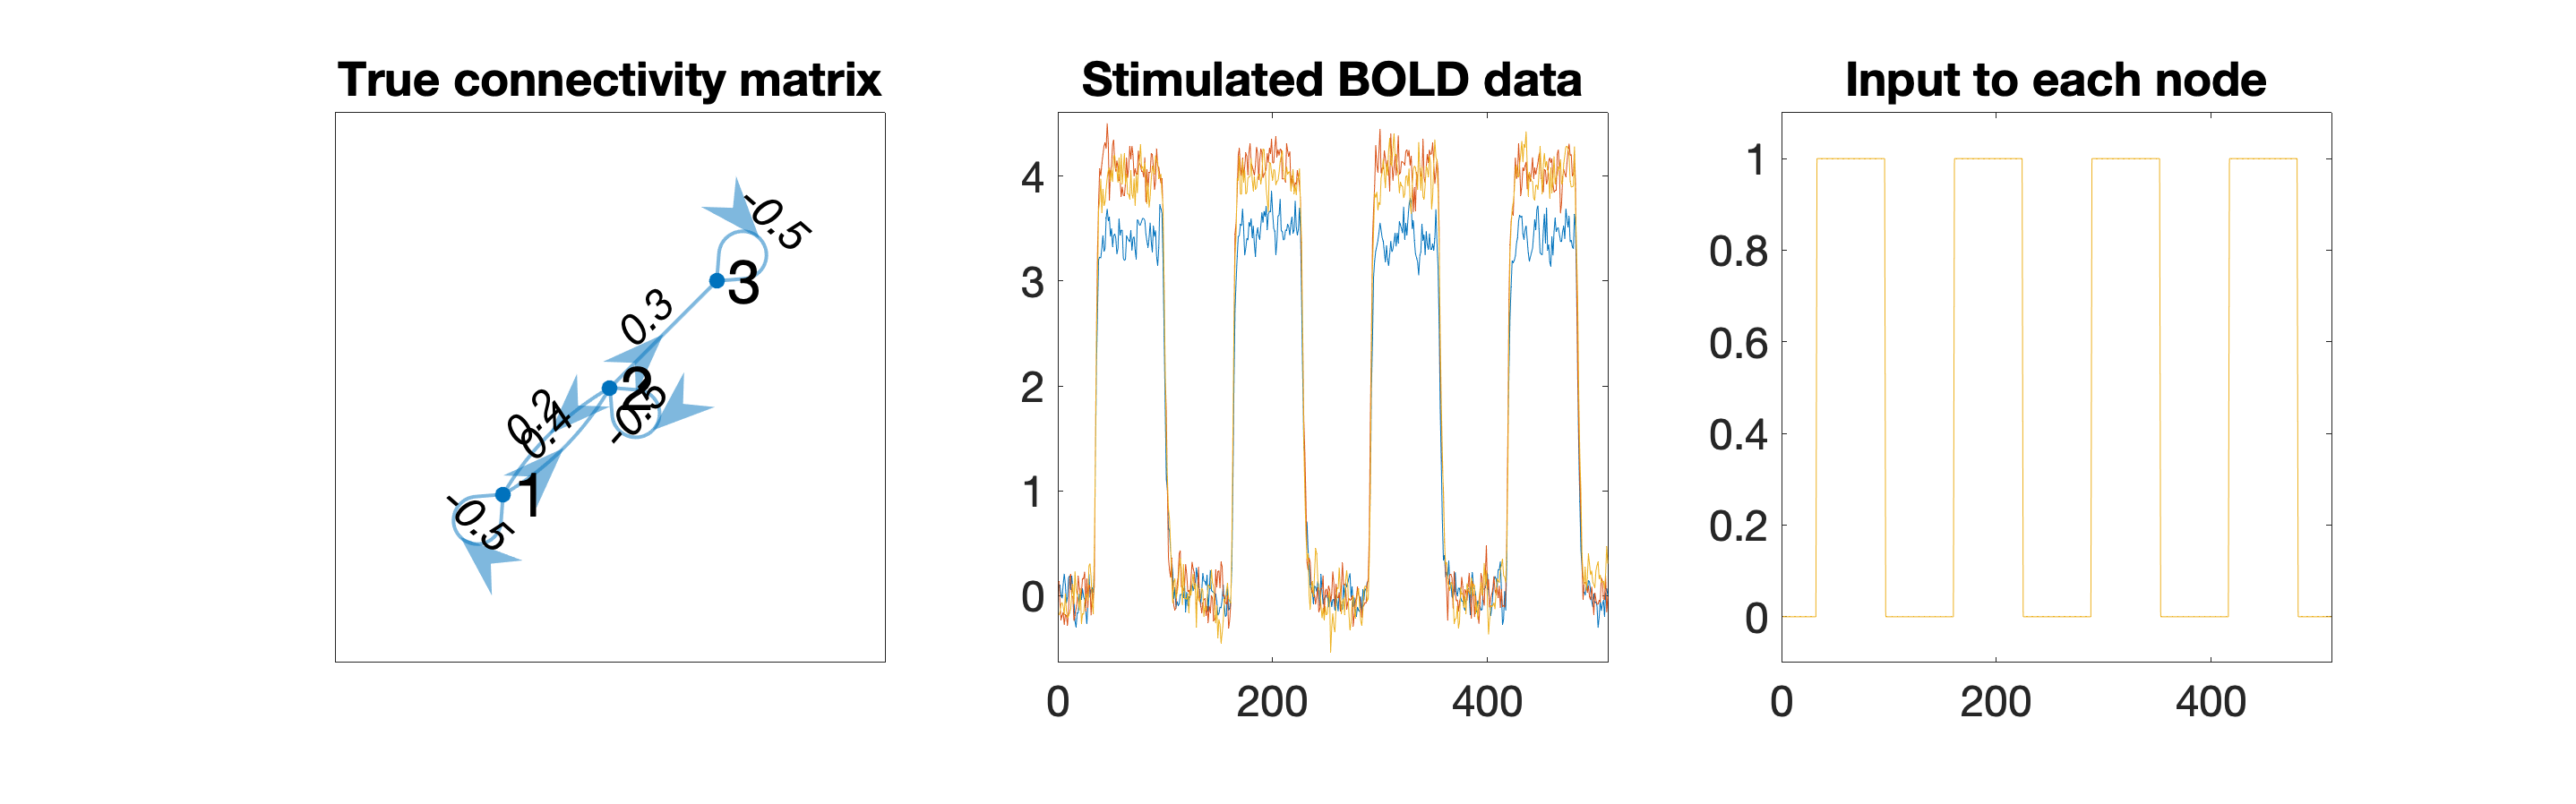

on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);

stim_options.u = zeros(stim_options.T, stim_options.n);
stim_node = [1,2,3];
for i=1:length(stim_node)
    stim_options.u(:, stim_node(i)) = tasktiming;   
end


[DCM, options] = make_DEM_demo_induced_fmri(stim_options);
plot_sim_data(DCM)

Invert simulated task with sparse rDCM

[output_sparse, options_sparse] = tapas_rdcm_estimate(DCM, 's', options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in tapas_dcm_euler_gen (line 54)
C = DCM.U.u*(Ep.C'/16);

Error in tapas_rdcm_generate (

Plot result

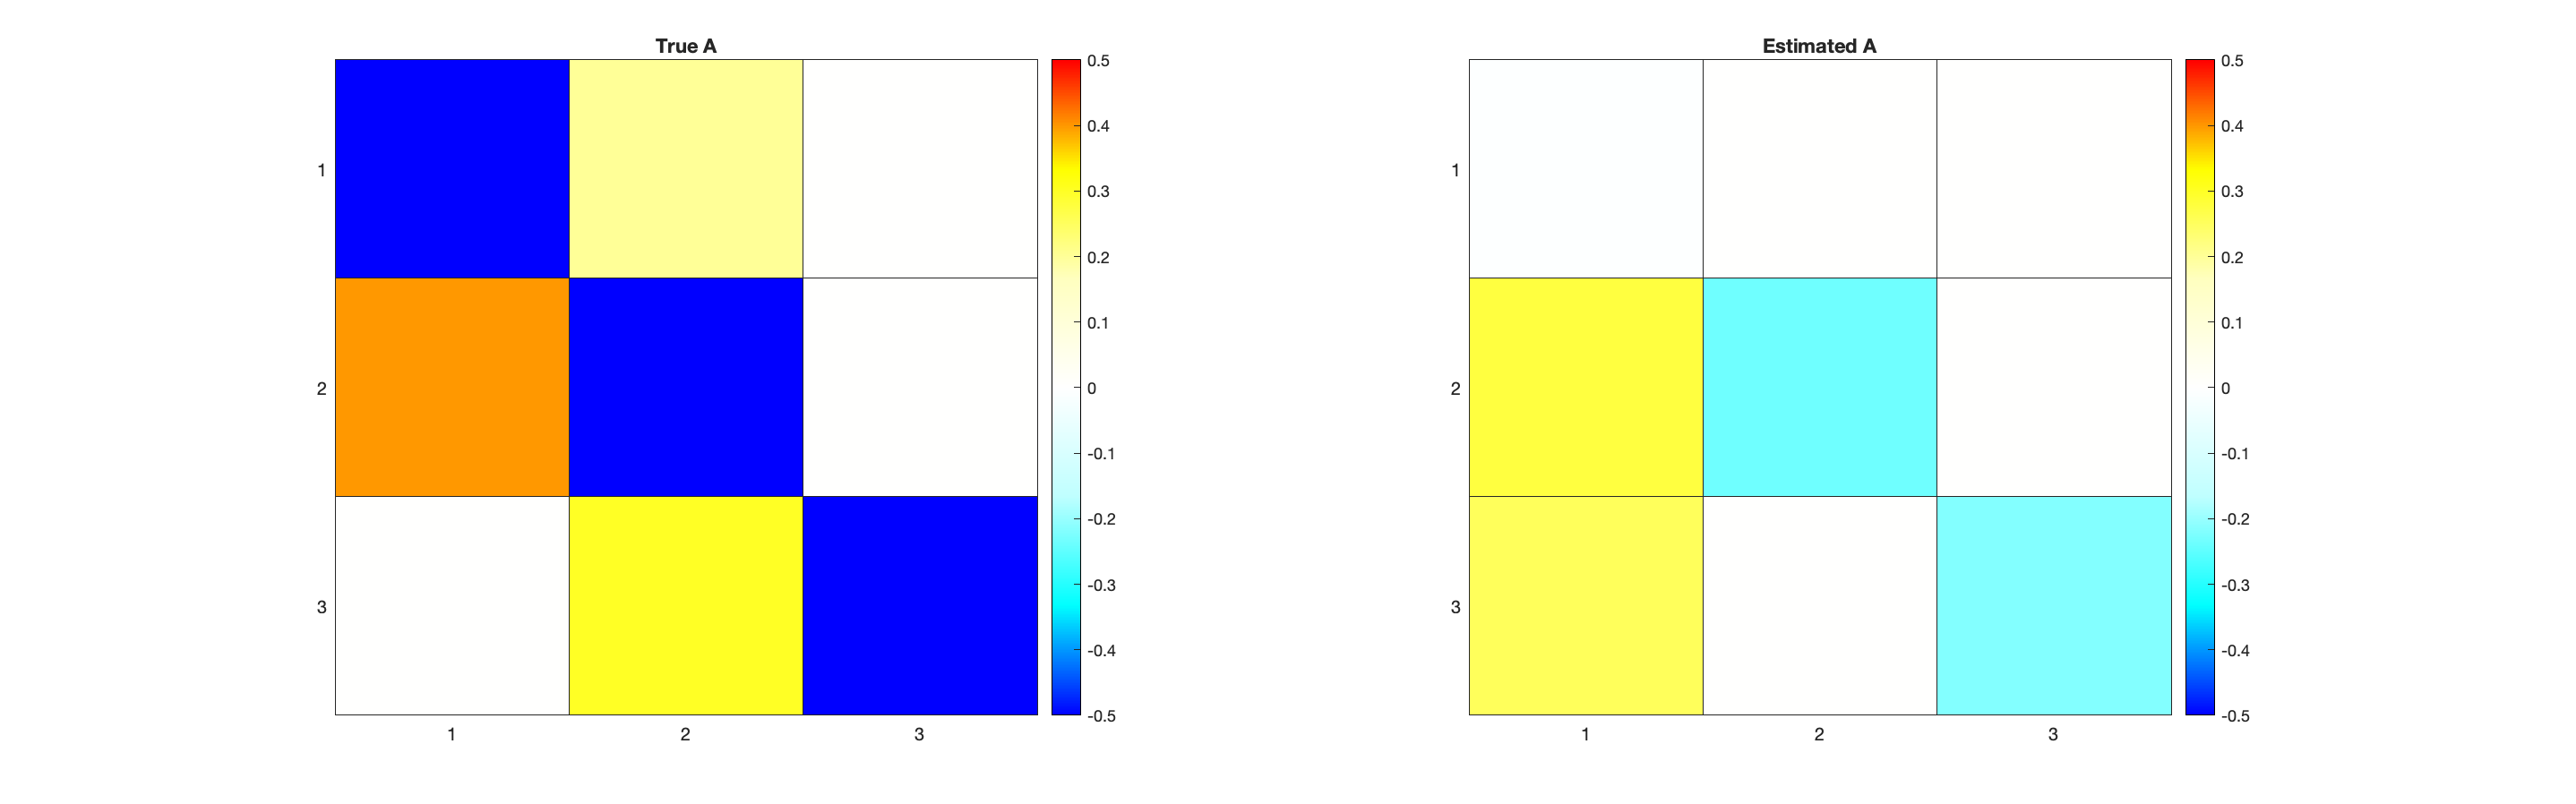

f = figure();

subplot(1, 2, 1)
h = heatmap(DCM.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A"); 

subplot(1, 2, 2)
h = heatmap(output_sparse.Ep.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("Estimated A"); 

set(f,'Units','normalized','Position',[0 0 1 .5]); 

## Short but frequent task to all nodes

## Long infrequent task to one node

## Long infrequent task to all nodes

## Average across multiple subjects

## Larger and sparser network